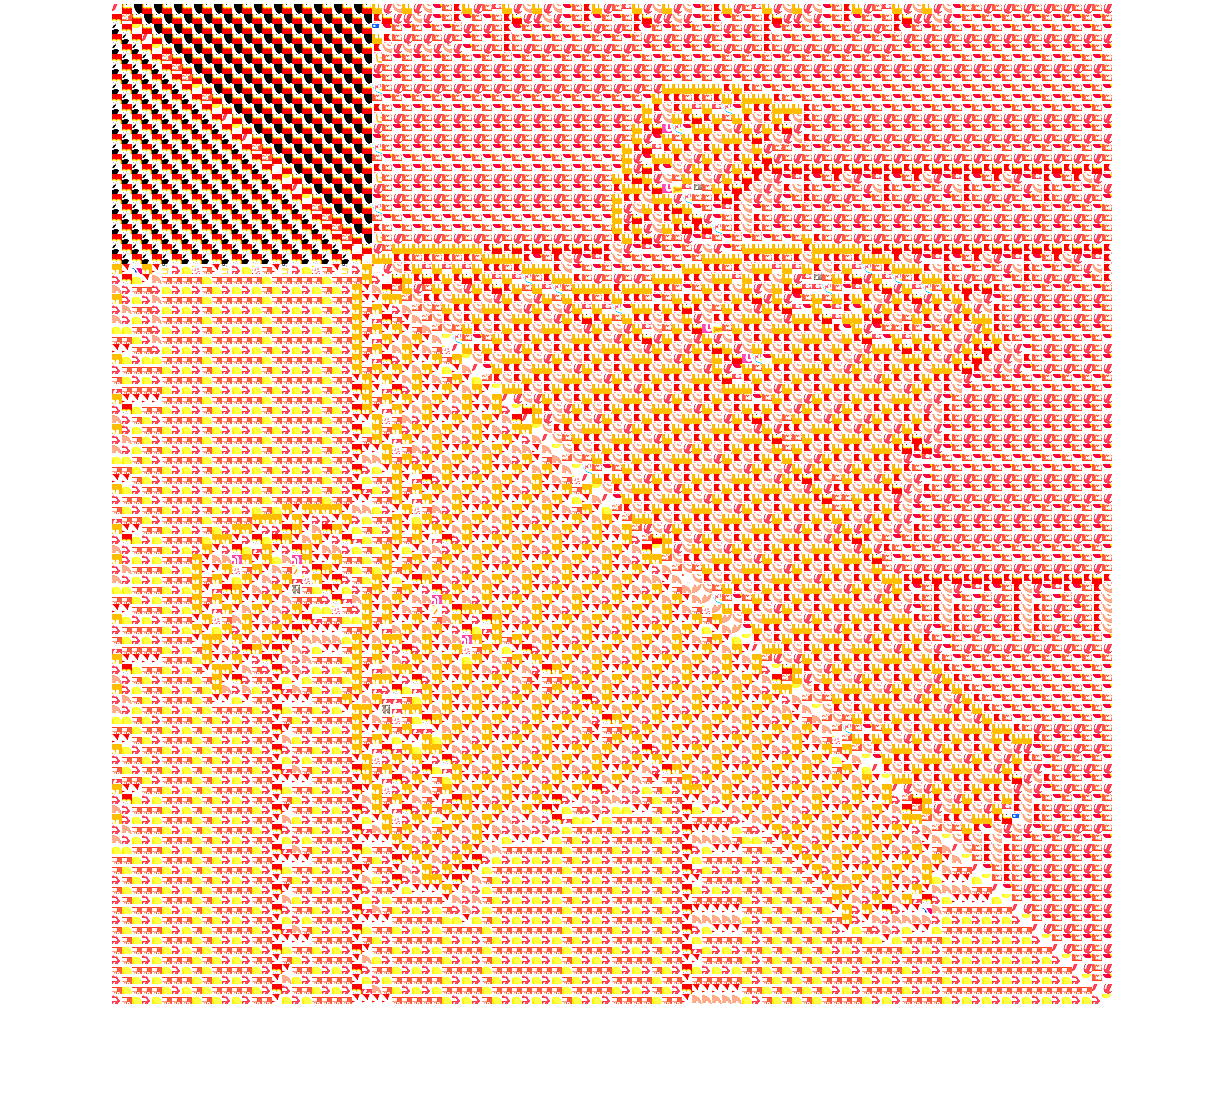

clear
clf

dataBase = cell(115, 1);

for i = 1:115
    dataBase{i} = imread(['Database_logos/' int2str(i) '.jpg']);
end

save dataBase dataBase

load dataBase.mat

numImages = numel(dataBase);

targetSize = [20, 20]; % -------------------Target size

for i = 1:numImages
    currentImage = dataBase{i};
    resizedImage = imresize(currentImage, targetSize);
    dataBase{i} = resizedImage;
end

save dataBase dataBase;

load dataBase

colorBase = cell(115, 1);

for i = 1:115
    
    currentImage = dataBase{i};
    
    labImage = rgb2lab(currentImage);
    
    L = labImage(:, :, 1);
    a = labImage(:, :, 2);
    b = labImage(:, :, 3);
    
    colorBase{i} = struct('L', L, 'a', a, 'b', b);
end

save colorBase colorBase

queryImage = imread("Database_logos/2.jpg"); 
queryImage = imresize(queryImage, [1000, 1000]);

queryImageLab = rgb2lab(queryImage);

QueryColorBase = cell(1, 1);
 
queryImageL = sum(sum(queryImageLab(:,:,1))); 
queryImagea = sum(sum(queryImageLab(:,:,2))); 
queryImageb = sum(sum(queryImageLab(:,:,3))); 
    
QueryColorBase{1} = struct('L', queryImageL, 'a', queryImagea, 'b', queryImageb);

save QueryColorBase QueryColorBase

load dataBase.mat
load colorBase.mat
load QueryColorBase.mat 

ActiveImages = cell(115,1);

gridSize = 10; % ---------------- GRID SIZE -------------------

numRows = size(queryImageLab, 1) / gridSize;
numCols = size(queryImageLab, 2) / gridSize;

QueryColorDominating = 'a'; 

for i = 1:numRows
    for j = 1:numCols
        % Dominating color in each region
        replaceRegion = [(i-1)*gridSize+1:i*gridSize, (j-1)*gridSize+1:j*gridSize];
        
        LChannel = queryImageLab(replaceRegion, replaceRegion, 1);
        aChannel = queryImageLab(replaceRegion, replaceRegion, 2);
        bChannel = queryImageLab(replaceRegion, replaceRegion, 3);
        
        % Use median instead of mean
        currentColor = [median(LChannel(:)), median(aChannel(:)), median(bChannel(:))];
        
        % Normalize the entire LAB vector
        currentColor = currentColor / norm(currentColor);
        
        currentDiff = inf;
        bestMatchIndex = 1; 
        
        % Calculate Euclidean distance for each image
        for q = 1:115
            targetColor = [median(colorBase{q}.L(:)), median(colorBase{q}.a(:)), median(colorBase{q}.b(:))];
            
            % Normalize the entire LAB vector
            targetColor = targetColor / norm(targetColor);
            
            distance = norm(currentColor - targetColor);
            
            if distance < currentDiff
                bestMatchIndex = q;
                currentDiff = distance;
            end   
        end

        insertedImage = dataBase{bestMatchIndex};
        queryImageLab(replaceRegion, replaceRegion, :) = insertedImage;

    end
end



imshow(queryImageLab / 100);